# Clear varibales ad workspace

clear all
close all
clc

## RADAR parameters

c=3e8 ;
Bw= 540e6;
R_max=125; %m
Vmax= 60*(1000/3600) ;
d_res=c/(2*Bw) ;

## Chirp

Tc= 45e-6 ; %125m / 45 us
S= Bw/Tc ;

fb_max= 10e6 ; %% 10 MHz
fs= 2.2*10e6  ;

% 2*S*R_max/c ; % R_max=(Fs*c)/(2*S) ;  Sampling frequency f_IF= 2*(S*d)/c   ;
d_res=c/(2*Bw) ;
t= (0:1/fs:Tc-1/fs) ;

## target 1

A1=0.1 ;
R1= 40 ; % target 1 Range
V1=0; % m/s
f_IF1= 2*(S*R1)/c;
S_T1=A1*cos(2*pi*f_IF1*t) ;

## target 2

A2=0.02 ;
R2= 70 ; % target 2 range
V2=0 ; % m/s
f_IF2= 2*(S*R2)/c ;
S_T2=A2*cos(2*pi*f_IF2*t) ;
S_IF_targets= (S_T1+S_T2) ;

## beat signal

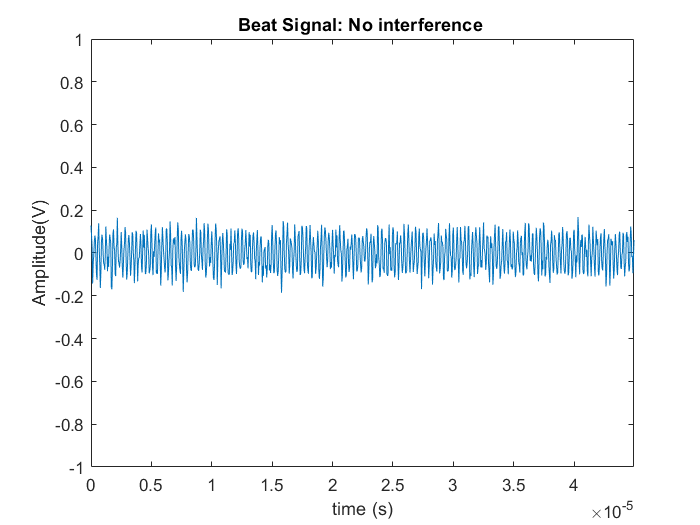

S_IF_targets=awgn(S_IF_targets,30) ; % total beat frequency signal
L=length(S_IF_targets) ;
figure
plot(t, S_IF_targets)
axis([0 max(t) -1 1])
title('Beat Signal: No interference ')
xlabel('time (s)')
ylabel('Amplitude(V)')


% figure 
% snr(S_IF_targets)
% title("snr of beat signal with 2 targets and no interference")

## Detcetion Based FFT

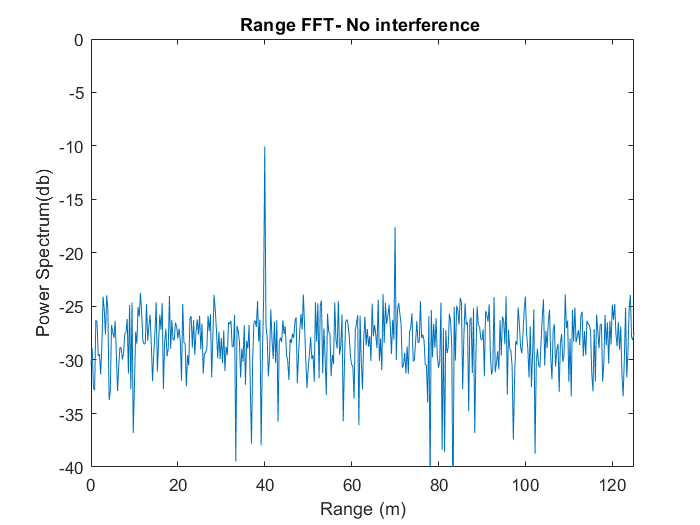

Y = fft(S_IF_targets);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
P1=pow2db(P1) ;
f = fs*(0:(L/2))/L;
%
figure
Rng=  (f*c)/(2*S);
plot(Rng,P1) 
axis([0 R_max -40 0]);
title('Range FFT- No interference ')
xlabel('Range (m)')
ylabel('Power Spectrum(db)')

## add interference

S_In=

PL = 0.4*Tc * fb_max;
tS = (0:PL-1)*(1/fb_max);  % Time vector
halfIdx = round(PL/2);
sFreq1=0.4*fb_max ;
sFreq2=0.7*fb_max ;

[S2_P1,phiEnd] = ChirpGenerate(sFreq1, sFreq2, t(1:halfIdx),90);
[S2_P2,phiEnd] = ChirpGenerate(sFreq2, sFreq1, t(1:halfIdx),phiEnd);
S2_P3= zeros(1,L-PL) ;
S2 = [S2_P3,S2_P1, S2_P2];
S2 = 0.2*S2 ;

## Tolal signal

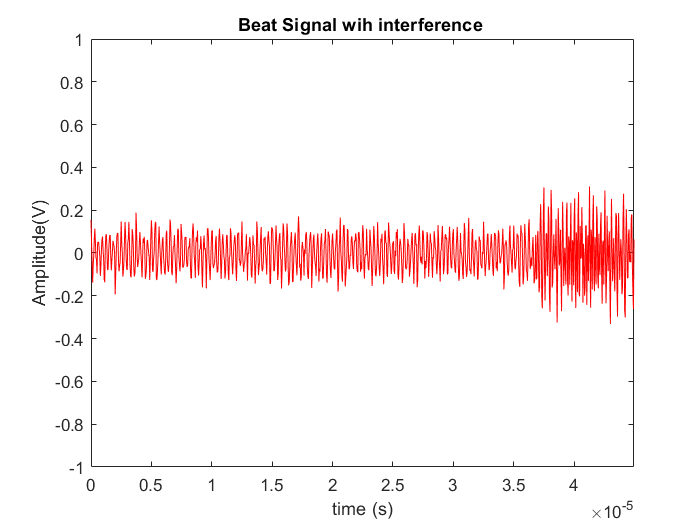

    S_IF= (S_T1+S_T2)+S2 ;
    S_IF=awgn(S_IF,30);
    figure
    plot(t, S_IF,'r') ;
    axis([0 max(t) -1 1])
    title('Beat Signal wih interference ')
    xlabel('time (s)')
    ylabel('Amplitude(V)')

    % figure 
    % snr(S_IF)
    % title("snr of total beat signal")

## Detection based FFT

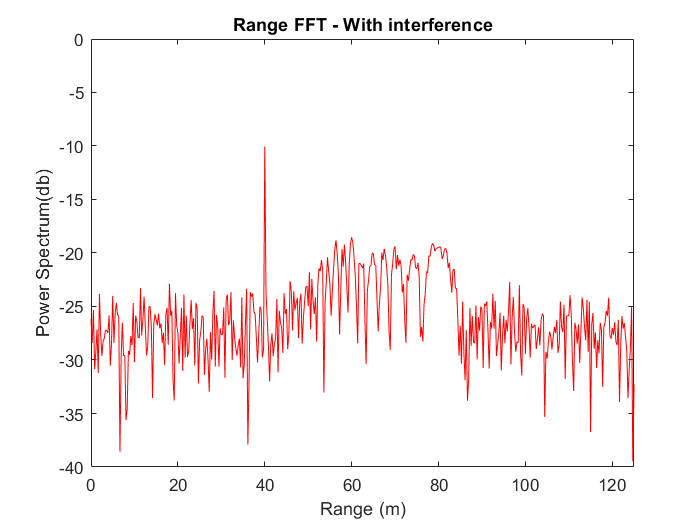

    Y = fft(S_IF);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1=pow2db(P1) ;
    f = fs*(0:(L/2))/L;
    Rng= (f*c)/(2*S);
    %
    figure
    plot(Rng,P1,'r') 
    axis([0 R_max -40 0]);
    title('Range FFT - With interference')
    xlabel('Range (m)')
    ylabel('Power Spectrum(db)')

## WEN

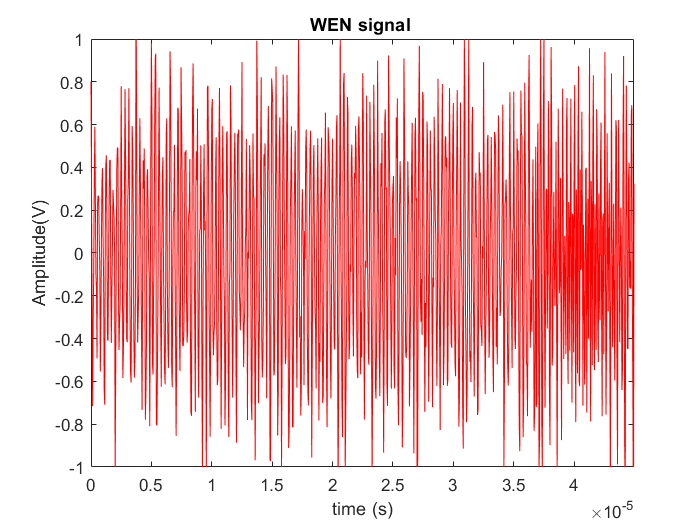

        [mlmax_F,mlmax_B,r,m_new] = WEN(S_IF,80) ;
        figure
        plot(t, m_new,'r') ;
        axis([0 max(t) -1 1])
        title('WEN signal ')
        xlabel('time (s)')
        ylabel('Amplitude(V)')

%         figure
%         snr(m_new)

## Detection based FFT

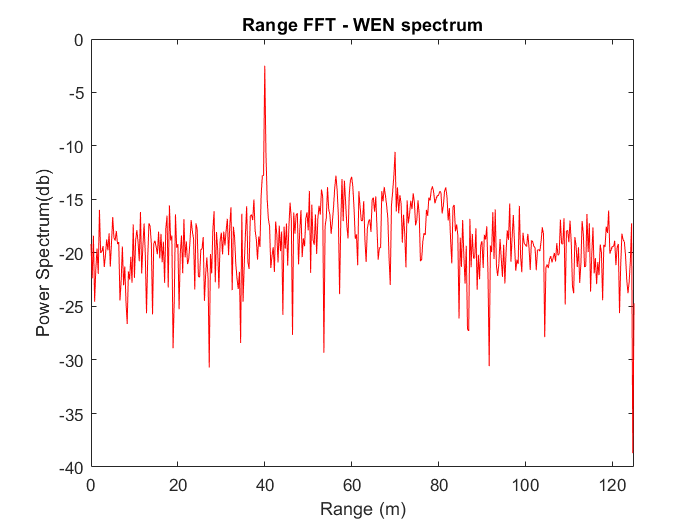

        Y = fft(m_new);
        P2 = abs(Y/L);
        P1 = P2(1:L/2+1);
        P1(2:end-1) = 2*P1(2:end-1);
        P1=pow2db(P1) ;
        f = fs*(0:(L/2))/L;
        Rng= (f*c)/(2*S);
        %
        figure
        plot(Rng,P1,'r') 
        axis([0 R_max -40 0]);
        title('Range FFT - WEN spectrum')
        xlabel('Range (m)')
        ylabel('Power Spectrum(db)')


% %% AWEN
% [mlmax_F,mlmax_B,r,m_new] = AWEN(S_IF,70,0.1) ; 
% figure
% plot(t, m_new,'r') ;
% axis([0 max(t) -1 1])
% title('WEN signal ')
% xlabel('time (s)')
% ylabel('Amplitude(V)')
% figure 
% % snr(m_new)
% %% Detection based FFT
% Y = fft(m_new);
% P2 = abs(Y/L);
% P1 = P2(1:L/2+1);
% P1(2:end-1) = 2*P1(2:end-1);
% P1=pow2db(P1) ;
% f = fs*(0:(L/2))/L;
% Rng= (f*c)/(2*S);
% %
% figure
% plot(Rng,P1,'r') 
% axis([0 R_max -40 0]);
% title('Range FFT - WEN spectrum')
% xlabel('Range (m)')
% ylabel('Power Spectrum(db)')